
    
    % 设置目标参数（在这里修改数值）
    target_range = 10;   % 水平距离 (米)
    target_height = -3;   % 垂直高度 (米) - 可以是负值！
    initial_velocity = 24; % 初速度 (米/秒)
    
    % 物理常数
    g = 9.81;
    
    fprintf('=== 弹道计算器 ===\n');

=== 弹道计算器 ===


    fprintf('目标距离: %.0f米\n', target_range);

目标距离: 10米


    fprintf('目标高度: %.0f米\n', target_height);

目标高度: -3米


    fprintf('发射初速: %.0f米/秒\n\n', initial_velocity);

发射初速: 24米/秒



    
    % 计算两个发射角度
    a = (g * target_range^2) / (2 * initial_velocity^2);
    b = -target_range;
    c = a + target_height;
    
    % 解二次方程
    discriminant = b^2 - 4*a*c;
    
    if discriminant < 0
        fprintf('错误：目标超出射程范围！\n');
        fprintf('建议：增加初速度或减小目标距离\n');
        return;
    end
    
    tan_theta1 = (-b + sqrt(discriminant)) / (2*a);
    tan_theta2 = (-b - sqrt(discriminant)) / (2*a);
    
    angle1 = atand(tan_theta1);
    angle2 = atand(tan_theta2);
    
    % 确保角度顺序：小角度在前
    if angle1 > angle2
        [angle1, angle2] = deal(angle2, angle1);
    end
    
    fprintf('计算完成！\n');

计算完成！


    fprintf('低角度: %.1f° (平直弹道)\n', angle1);

低角度: -11.9° (平直弹道)


    fprintf('高角度: %.1f° (高抛弹道)\n\n', angle2);

高角度: 85.2° (高抛弹道)



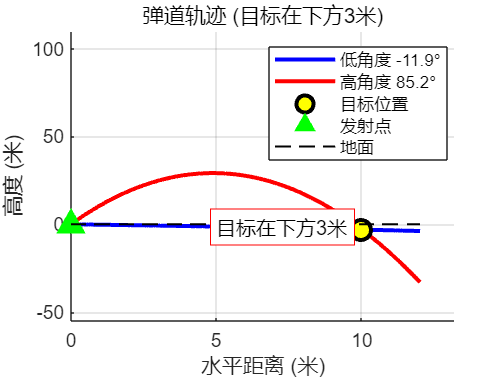

    
    % 绘制弹道轨迹
    figure('Name', '弹道轨迹图', 'NumberTitle', 'off');
    hold on;
    
    % 计算并绘制低角度轨迹
    theta_low = deg2rad(angle1);
    % 计算飞行时间（考虑可能的下落）
    t_max_low = (initial_velocity * sin(theta_low) + ...
                sqrt((initial_velocity * sin(theta_low))^2 + 2 * g * abs(min(0, target_height)))) / g;
    t_low = linspace(0, t_max_low * 1.2, 200);
    x_low = initial_velocity * cos(theta_low) * t_low;
    y_low = initial_velocity * sin(theta_low) * t_low - 0.5 * g * t_low.^2;
    plot(x_low, y_low, 'b-', 'LineWidth', 2);
    
    % 计算并绘制高角度轨迹  
    theta_high = deg2rad(angle2);
    t_max_high = (initial_velocity * sin(theta_high) + ...
                 sqrt((initial_velocity * sin(theta_high))^2 + 2 * g * abs(min(0, target_height)))) / g;
    t_high = linspace(0, t_max_high * 1.2, 200);
    x_high = initial_velocity * cos(theta_high) * t_high;
    y_high = initial_velocity * sin(theta_high) * t_high - 0.5 * g * t_high.^2;
    plot(x_high, y_high, 'r-', 'LineWidth', 2);
    
    % 标记目标点
    plot(target_range, target_height, 'ko', 'MarkerSize', 10, ...
         'MarkerFaceColor', 'yellow', 'LineWidth', 2);
    
    % 标记发射点
    plot(0, 0, 'g^', 'MarkerSize', 12, 'MarkerFaceColor', 'green');
    
    % 画地面线
    plot([0, max(x_low(end), x_high(end))], [0, 0], 'k--', 'LineWidth', 1);
    
    grid on;
    xlabel('水平距离 (米)');
    ylabel('高度 (米)');
    
    if target_height < 0
        title(sprintf('弹道轨迹 (目标在下方%.0f米)', abs(target_height)));
    else
        title(sprintf('弹道轨迹 (目标在上方%.0f米)', target_height));
    end
    
    legend(sprintf('低角度 %.1f°', angle1), ...
           sprintf('高角度 %.1f°', angle2), ...
           '目标位置', '发射点', '地面', 'Location', 'best');
    
    % 设置坐标轴
    max_x = max([x_low(end), x_high(end), target_range]);
    max_y = max([max(y_low), max(y_high), abs(target_height), 100]);
    min_y = min([min(y_low), min(y_high), target_height, -50]);
    
    xlim([0, max_x * 1.1]);
    ylim([min_y * 1.1, max_y * 1.1]);
    
    % 添加高度标注
    if target_height < 0
        text(target_range/2, target_height/2, ...
             sprintf('目标在下方%.0f米', abs(target_height)), ...
             'BackgroundColor', 'white', 'EdgeColor', 'red');
    end

    
    fprintf('图形已显示！\n');

图形已显示！


    fprintf('要计算其他目标，请修改代码中的 target_range, target_height, initial_velocity 值。\n');

要计算其他目标，请修改代码中的 target_range, target_height, initial_velocity 值。
